# Phase Portrait for Marble Track

clear; close all; clc

% creates two matrices:
% one for all the x-values on the grid (constant columns)
% one for all the y-values on the grid (constant rows)
y1 = linspace(-2,2,10);
y2 = linspace(-4,4,10);
[X,Y] = meshgrid(y1,y2);

Computing the Vector Field

% Generate two matrices, u and v. 
% U contains the value of y1'(0) at each x and y position
% V contains the value of y2'(0) at each x and y position
U = zeros(size(X));
V = zeros(size(Y));
t = 0;

% numel iterates over the 1st column, then 2nd, ...
% (could probably use gradient() instead)
for i = 1:numel(X)
    y_dot = f(t, [X(i); Y(i)]); % state space equation
    U(i) = y_dot(1);
    V(i) = y_dot(2);
end

Plot the Vector Field

quiver(X,Y,U,V,'k');
xlabel('x_1 (m)')
ylabel('x_2 (m/s)')
title('Vector Field for Frictionless Marble Track')

Plotting solutions on the vector field for different initial conditions:

 
$$y_1(0)=y_{10}, \\
y_2(0)=0$$


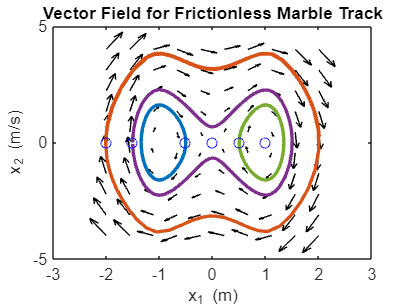

hold on
for y10 = [-2, -1.5, 1, -0.5, 0, 0.5]
    [ts,ys] = ode45(@f,[0,4.5],[y10; 0]);
    plot(ys(:,1),ys(:,2),'LineWidth',2)
    plot(ys(1,1),ys(1,2),'bo') % starting point
end
hold off

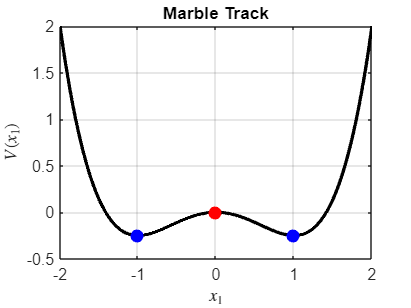

close all
x = linspace(-2,2,1000);
V = 1/4*x.^4 - 1/2*x.^2;
plot(x,V,'k','LineWidth',2)
title('Marble Track'); grid on;
hold on
scatter([-1,1],-1/4*[1,1],60,'b','filled')
scatter(0,0,60,'r','Filled')
xlabel('$x_1$',Interpreter='latex')
ylabel('$V(x_1)$',Interpreter='latex')
hold off

function [vp] = Vprime(x)
    vp = x^3-x;
end

function [y_dot] = f(~,y)
k = 6*pi*0.008*1.45*10^-5;
c = 0.1;
m = 4.5e-3;
g = 9.81;
vp = Vprime(y(1));
Delta = sqrt(1 + vp^2);

k=0;
c=0;

y_dot(1,:) = y(2);
y_dot(2,:) = -k/m*y(2) - c*g/Delta*sign(y(2)) - g*vp/Delta;
end
